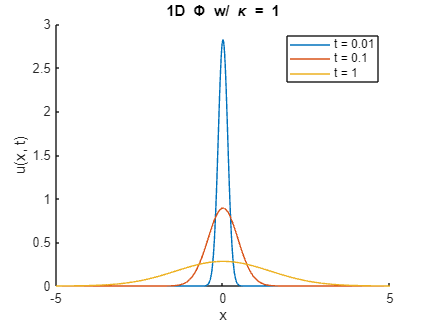

% Define the range for x
x = linspace(-5, 5, 1000);

% Define the time values
t_values = [0.01, 0.1, 1.0];

% Initialize the figure
figure;
hold on;

% Loop over each time value
for t = t_values
    % Compute the fundamental solution
    u = (1 / sqrt(4 * pi * t)) * exp(-x.^2 / (4 * t));
    % Plot the solution
    plot(x, u, 'DisplayName', ['t = ', num2str(t)]);
end

% Label the axes
xlabel('x');
ylabel('u(x, t)');
title('1D \Phi w/ \kappa = 1');

% Add a legend to indicate the three times
legend('show');

% Release the hold on the plot
hold off;